## plot one channel's spectrum

chann_num = 1

chann_num = 1

sample_from_batch_num = 1

sample_from_batch_num = 1

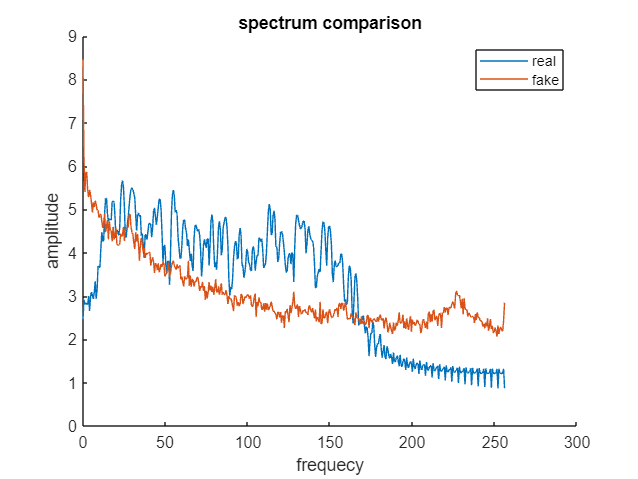

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
clf
% spectrum_real = spectral_real(sample_from_batch_num, chann_num, :);
% spectrum_fake = spectral_fake(sample_from_batch_num, chann_num, :);
spectrum_real = spectral_real(:, chann_num, :);
spectrum_fake = spectral_fake(:, chann_num, :);
spectrum_real = mean(spectrum_real, 1);
spectrum_fake = mean(spectrum_fake, 1);
spectrum_real = spectrum_real(:);
spectrum_fake = spectrum_fake(:);
hold on 
plot(freqs, spectrum_real, 'DisplayName', 'real')
plot(freqs, spectrum_fake, 'DisplayName', 'fake')
hold off

title('spectrum comparison')
xlabel('frequecy')
ylabel('amplitude')
legend

## plot all channels spectrum

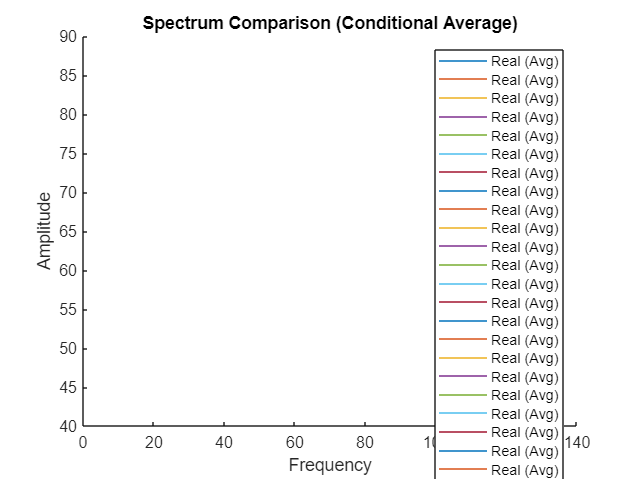

sample_from_batch_num = 1;

% Define the condition for averaging (replace with your specific condition)
average_condition = true;  % Example condition, replace with your logic

if average_condition
  % Calculate average spectrum across channels
  spectrum_real = mean(squeeze(spectral_real(sample_from_batch_num, :, :)), 1);
  spectrum_fake = mean(squeeze(spectral_fake(sample_from_batch_num, :, :)), 1);
else
  spectrum_real = squeeze(spectral_real(sample_from_batch_num, :, :)); 
  spectrum_fake = squeeze(spectral_fake(sample_from_batch_num, :, :));
end

% Plotting
hold_on = true;  % Adjust based on your preference

figure;  % Create a new figure window

if hold_on
  hold on;  % Enable hold for plotting on the same figure
end

plot(freqs, spectrum_real, 'DisplayName', 'Real (Avg)');
plot(freqs, spectrum_fake, 'DisplayName', 'Fake (Avg)');

if hold_on
  hold off;  % Disable hold if using hold_on
end

title('Spectrum Comparison (Conditional Average)');
xlabel('Frequency');
ylabel('Amplitude');
legend;

## plot one channel's raw samples

chann_num = 1

chann_num = 1

sample_from_batch_num = 2

sample_from_batch_num = 2

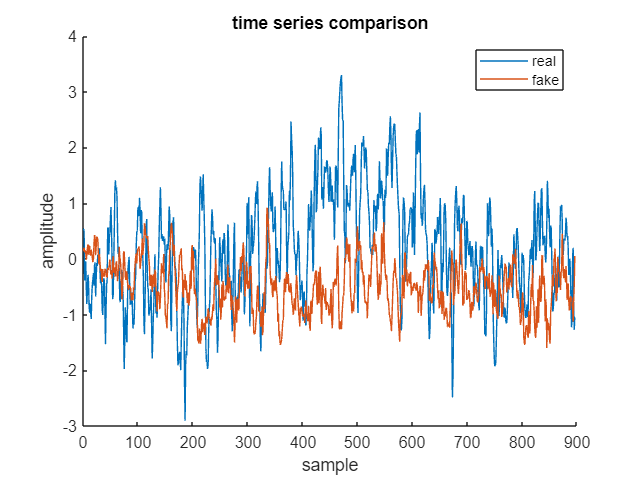

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
clf
signal_real = squeeze(X_real(sample_from_batch_num, chann_num, :));
signal_fake = squeeze(X_fake(sample_from_batch_num, chann_num, :));
hold on 
plot(signal_real, 'DisplayName', 'real')
plot(signal_fake, 'DisplayName', 'fake')
hold off

title('time series comparison')
xlabel('sample')
ylabel('amplitude')
legend

## plot all channels raw samples

sample_from_batch_num = 1

sample_from_batch_num = 1

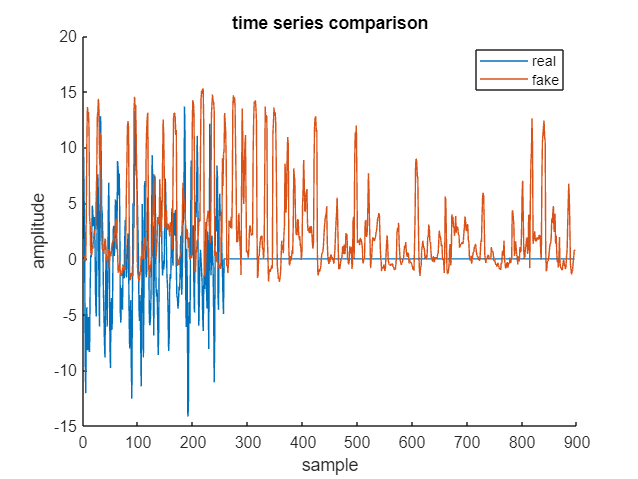

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
clf
signal_real = squeeze(X_real(sample_from_batch_num, :, :))';
signal_fake = squeeze(X_fake(sample_from_batch_num, :, :))';
hold on 
plot(signal_real, 'DisplayName', 'real')
plot(signal_fake, 'DisplayName', 'fake')
hold off

title('time series comparison')
xlabel('sample')
ylabel('amplitude')
legend

## plot one channel's spectrum calculated from raw signals

clf
% plot_fft_stats(X_real)

X=X_real(:,:,1:256); % remove latest zero values
X = permute(X, [3 1 2]);
% if nargin == 1
name = '';
% end
Fs = 256;
L = 256;
BS=buffer(X,256,0);

Error using buffer
Input must be a vector.

P1_all = zeros([size(BS, 2), 129]);
BS = X;
for i = 1:size(BS, 2)
    f = Fs*(0:(L/2))/L;
    Y = fft(BS(:, i)');
    P2 = abs(Y/L);
    P1 = P2(1:L/2+1);
    P1(2:end-1) = 2*P1(2:end-1);
    P1_all(i, :) = P1;
end
P1_means = mean(P1_all, 1);
P1_max = max(P1_all, [], 1);
P1_min = min(P1_all, [], 1);
hold on
plot(f, P1_max,'--', 'DisplayName', strcat([name, '-max']));
plot(f, P1_means, 'DisplayName', strcat([name, '-avg']));
plot(f, P1_min,'--', 'DisplayName', strcat([name, '-min']));
% plot(f,P1_means+std(P1_all, [], 1),'--');
% plot(f,P1_means-std(P1_all, [], 1),'--');
legend
hold off
xlabel("f (Hz)")
ylabel("|P1(f)|")

## calculate statistics from signals

chann_idx = 1;
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Calculate statistics from real data
stats_real = calculate_statistics(X_real(:,chann_idx,:));
% Access results
disp('Real data statistics');

Real data statistics


disp(['Mean: ', num2str(stats_real.mean)]);

Mean: 0.00029898


disp(['Standard deviation:', num2str(stats_real.std)]);

Standard deviation:2.4107


disp(['Minimum value:', num2str(stats_real.min)]);

Minimum value:-11.6086


disp(['Maximum value:', num2str(stats_real.max)]);

Maximum value:14.2905



% Calculate statistics from fake data
stats_fake = calculate_statistics(X_fake(:,chann_idx,:));
% Access results
disp('Fake data statistics');

Fake data statistics


disp(['Mean: ', num2str(stats_fake.mean)]);

Mean: 4.1422


disp(['Standard deviation:', num2str(stats_fake.std)]);

Standard deviation:15.5153


disp(['Minimum value:', num2str(stats_fake.min)]);

Minimum value:-29.4821


disp(['Maximum value:', num2str(stats_fake.max)]);

Maximum value:35.2773


## plot histogram

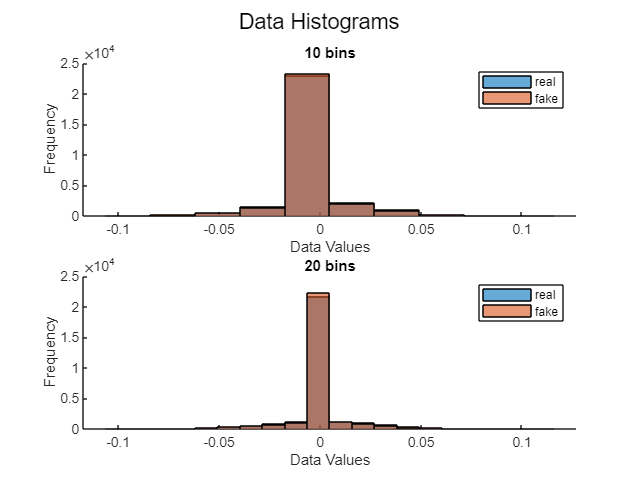

chann_idx = 1;
nbins = [10, 20];
data_real = X_real(:,chann_idx,:);
data_fake = X_fake(:,chann_idx,:);
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

plot_histograms_real_fake(data_real, data_fake, nbins);

## functions

function plot_fft_stats_already_buffered(X, name)
if nargin == 1
    name = '';
end
Fs = 256;
L = 256;
% BS=buffer(X,256,0);
% P1_all = zeros([size(BS, 2), 129]);
BS = X;
for i = 1:size(BS, 2)
    f = Fs*(0:(L/2))/L;
    Y = fft(BS(:, i)');
    P2 = abs(Y/L);
    P1 = P2(1:L/2+1);
    P1(2:end-1) = 2*P1(2:end-1);
    P1_all(i, :) = P1;
end
P1_means = mean(P1_all, 1);
P1_max = max(P1_all, [], 1);
P1_min = min(P1_all, [], 1);
hold on
plot(f, P1_max,'--', 'DisplayName', strcat([name, '-max']));
plot(f, P1_means, 'DisplayName', strcat([name, '-avg']));
plot(f, P1_min,'--', 'DisplayName', strcat([name, '-min']));
% plot(f,P1_means+std(P1_all, [], 1),'--');
% plot(f,P1_means-std(P1_all, [], 1),'--');
legend
hold off
xlabel("f (Hz)")
ylabel("|P1(f)|")
end

function stats = calculate_statistics(data)

%   This function calculates statistics (mean, standard deviation, minimum, maximum)
%   from a 3D MATLAB array.
%   Args:
%       data: A 3D MATLAB array.
%   Returns:
%       A structure 'stats' containing the calculated statistics.

  % Input validation
  if size(data, 2) ~= 1
    error('Input data must be a 3D matrix with a single channel.');
  end
  data = permute(data, [1 3 2]);
  % Calculate statistics
  stats.mean = mean(data, "all");
  stats.std = std(data, 0,"all");
  stats.min = min(data(:));  % Use colon (:) for all elements
  stats.max = max(data(:));

end

function plot_histograms_real_fake(data_real, data_fake, nbins)
  clf

  % Get minimum and maximum values from both data sets
  min_value = min(cat(1, data_real, data_fake), [], 'all');
  max_value = max(cat(1, data_real, data_fake), [], 'all');

  % Number of subplots based on the length of nbins vector
  num_subplots = length(nbins);

  % Loop through each nbins value and create subplots
  for i = 1:num_subplots
    current_nbins = nbins(i);
    bin_width = (max_value - min_value) / current_nbins;
    edges = linspace(min_value, max_value, current_nbins + 1);

    % Create subplot for each nbins value
    subplot(num_subplots, 1, i);

    % Plot histograms for real and fake data
    hold on
    hist_real = histogram(data_real, edges, 'DisplayName', 'real');
    hist_fake = histogram(data_fake, edges, 'DisplayName', 'fake');
    hold off

    % Adjust subplot title and labels (optional)
    title(sprintf('%.0f bins', current_nbins));
    xlabel('Data Values');
    ylabel('Frequency');
    legend;
  end

  % Adjust overall figure title and labels (optional)
  sgtitle('Data Histograms');  % Sets title for the whole figure
  xlabel('Data Values');
  ylabel('Frequency');
end
